**66010892 อดิศร สมมาตร**

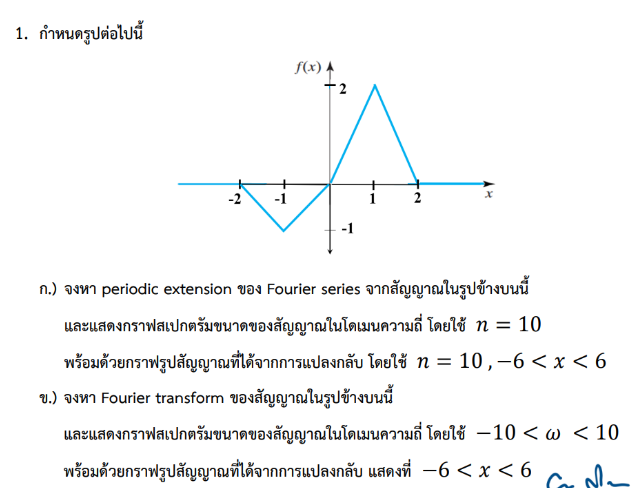

clc;clf;clear;
close all;
syms t w;
f = piecewise(t < -1, -t-1, t >= -1 & t < 1, 2*t, t >= 1, -t+1);

**ก) Plot the original signal**

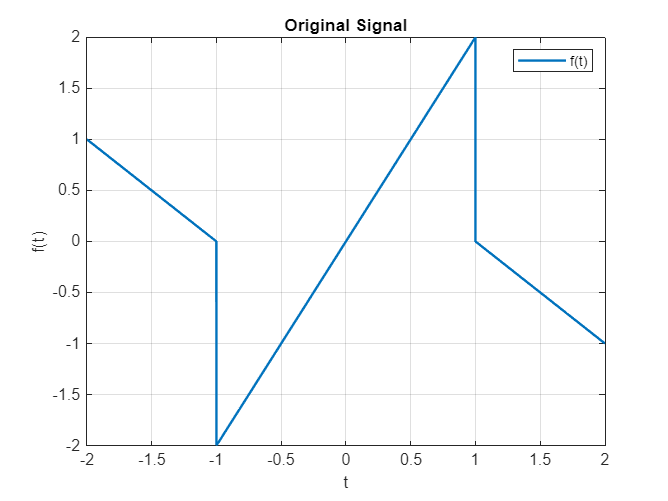

figure;
fplot(f, [-2, 2], 'LineWidth', 1.5);
grid on;
title('Original Signal');
xlabel('t');
ylabel('f(t)');
legend('f(t)');

**Fourier Series Approximation**

L = 4;  % Period
n = 10; % Number of terms 
a0 = (1/L) * int(f, t, -2, 2);
fourier_series = a0 / 2;
for k = 1:n
    ak = (2/L) * int(f * cos(k * pi * t / 2), t, -2, 2);
    bk = (2/L) * int(f * sin(k * pi * t / 2), t, -2, 2);
    fourier_series = fourier_series + ak * cos(k * pi * t / 2) + bk * sin(k * pi * t / 2);
end
F_w = fourier(f, t, w);

**Plot Fourier Series Approximation **

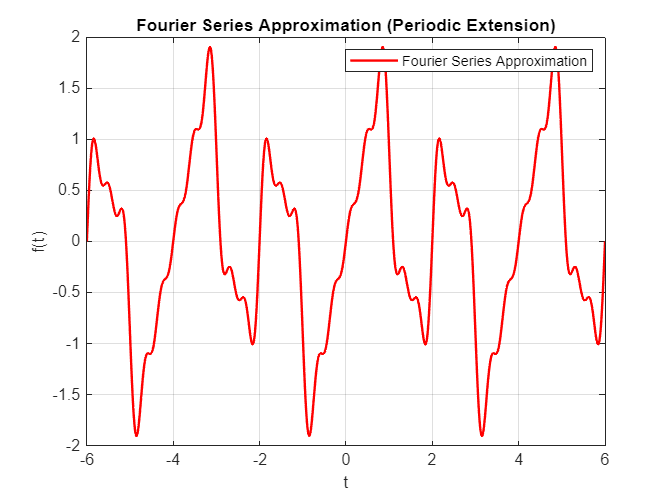

figure;
fplot(fourier_series, [-6, 6], 'r', 'LineWidth', 1.5);
grid on;
title('Fourier Series Approximation (Periodic Extension)');
xlabel('t');
ylabel('f(t)');
legend('Fourier Series Approximation');

**Show result Fourier Series Expression**

disp('Fourier Series Expression:');

Fourier Series Expression:


disp(vpa(fourier_series, 4)); 

$$0.3183\,\sin\left(9.425\,t\right)-0.3473\,\sin\left(4.712\,t\right)-0.1158\,\sin\left(11.0\,t\right)+0.5792\,\sin\left(1.571\,t\right)+0.9549\,\sin\left(3.142\,t\right)-0.1592\,\sin\left(6.283\,t\right)-0.07958\,\sin\left(12.57\,t\right)-0.05572\,\sin\left(14.14\,t\right)-0.07869\,\sin\left(7.854\,t\right)+0.191\,\sin\left(15.71\,t\right)$$

**ข)**

**Show result Fourier Transform Expression**

disp('Fourier Transform Expression:');

Fourier Transform Expression:


disp(vpa(F_w, 4));  

$$\mathrm{fourier}\left(\left\{ \begin{array}{cl} -t-1 & \text{ if }t<-1\\ 2\,t & \text{ if }t\in \left[-1,1\right)\\ 1-t & \text{ if }1\leq t \end{array}\right.,t,w\right)$$

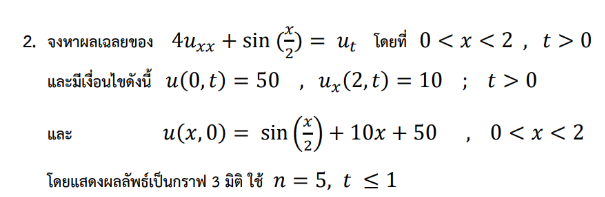

clearvars; clf; clc;
L = 2;               
N = 5;               
dx = L / (N-1);       
x = linspace(0, L, N); 
T = 1;                
dt = 0.01;           
t = 0:dt:T;        
u = zeros(N, length(t));
u(:,1) = sin(x/2) + 10*x + 50;
alpha = dt / (dx^2);
for n = 1:length(t)-1
    for i = 2:N-1
        u(i,n+1) = u(i,n) + 4*alpha * (u(i+1,n) - 2*u(i,n) + u(i-1,n)) + ...
                   dt * sin(x(i)/2); 
    end   
    u(1,n+1) = 50; 
    u(N,n+1) = u(N-1,n+1) + dx * 10;
end

**Plot 3D graph**

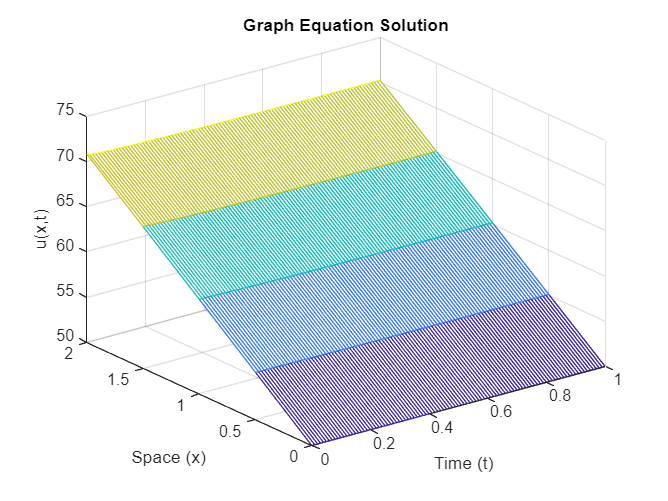

figure;
mesh(t, x, u);
xlabel('Time (t)');
ylabel('Space (x)');
zlabel('u(x,t)');
title('Graph Equation Solution');

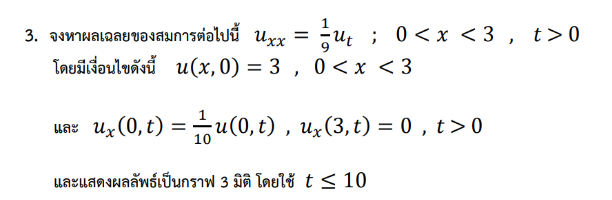

clearvars; clf; clc;
L = 3;          
T = 10;             
N = 20;             
M = 1000;           
dx = L / (N-1);    
dt = T / M;        
x = linspace(0, L, N); 
t = linspace(0, T, M); 
u = zeros(N, M);    
u(:,1) = 3;        
alpha = dt / (9 * dx^2); 
for n = 1:M-1
    for i = 2:N-1
        u(i, n+1) = u(i, n) + alpha * (u(i+1, n) - 2*u(i, n) + u(i-1, n));
    end
    u(1, n+1) = u(1, n) + alpha * (u(2, n) - u(1, n));  
    u(N, n+1) = u(N-1, n+1); 
end

**Plot graph 3D**

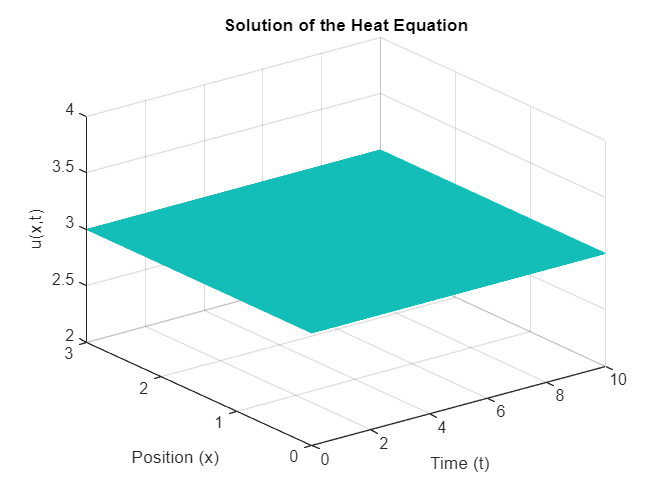

figure;
mesh(t, x, u);
xlabel('Time (t)');
ylabel('Position (x)');
zlabel('u(x,t)');
title('Solution of the Heat Equation');

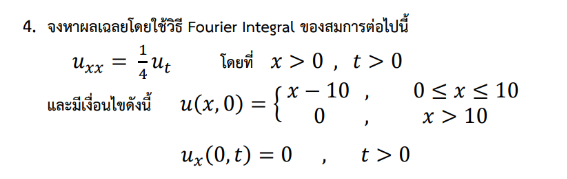

clearvars;clf;clc;
syms u(x,t) k

**initial condition u(x,0) as piecewise**

u_initial = piecewise(0 <= x & x <= 10, x - 10, x > 10, 0);
u_hat_k = fourier(u_initial, x, k);

**solve ODE**

u_hat_k_t = u_hat_k * exp(-k^2 * t / 4);
u_solution = ifourier(u_hat_k_t, k, x);

**Display the solution**

disp('The solution u(x,t) is:')

The solution u(x,t) is:


disp(u_solution)

$$\frac{\mathrm{fourier}\left({\mathrm{e}}^{-\frac{k^{2}\,t}{4}}\,\mathrm{fourier}\left(\left\{ \begin{array}{cl} x-10 & \text{ if }x\in \left[0,10\right]\\ 0 & \text{ if }10<x \end{array}\right.,x,k\right),k,-x\right)}{2\,\pi }$$

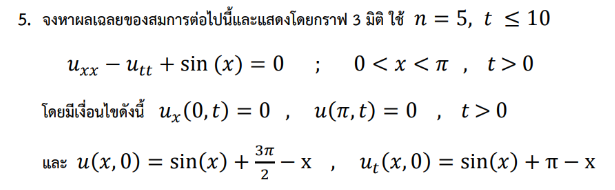

clearvars; clf; clc;
L = pi;               
T = 10;               
n = 5;             
m = 500;             
dx = L / (n-1);      
dt = T / m;            
x = linspace(0, L, n);
t = linspace(0, T, m);
u = zeros(n, m);       
u(:,1) = sin(x) + (3*pi/2 - x);  
u(:,2) = sin(x) + (pi - x);      
for k = 2:m-1
    for i = 2:n-1
        u(i, k+1) = 2*(1 - 2*dt^2/dx^2)*u(i,k) - u(i,k-1) + (dt^2 * sin(x(i))) + (dt^2 / dx^2) * (u(i+1, k) - 2*u(i,k) + u(i-1, k));
    end
    u(1, k+1) = u(1, k);  
    u(n, k+1) = 0;        
end

**Plot 3D**

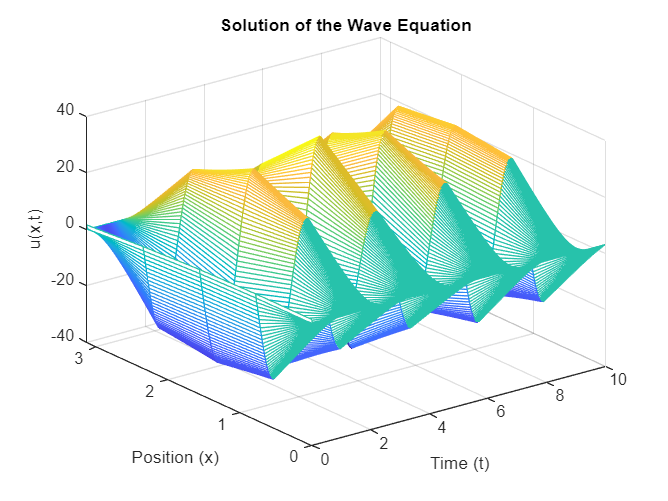

figure;
mesh(t, x, u);
xlabel('Time (t)');
ylabel('Position (x)');
zlabel('u(x,t)');
title('Solution of the Wave Equation');

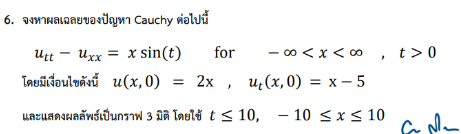

clearvars;clc;clf;

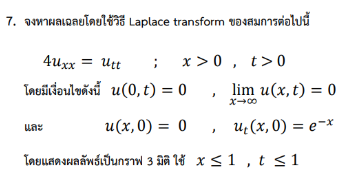

clearvars;
syms u(x,t) k h lambda;

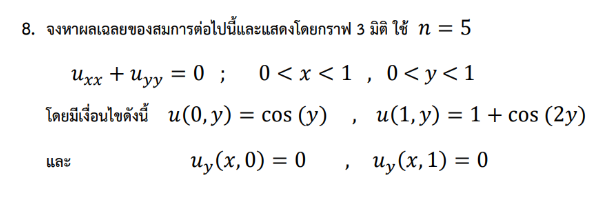

clearvars;clf;clc;
L = 1; 
n = 5;
u0 = @(y) cos(y); 
u1 = @(y) 1 + cos(2 * y); 
du0 = @(x) 0; 
du1 = @(x) 0; 
[x, y] = meshgrid(linspace(0, L, n), linspace(0, L, n));
u = zeros(n, n);
for i = 1:n
    for j = 1:n
        u(i, j) = u0(y(j)) + (u1(y(j)) - u0(y(j))) * (x(i) / L);
    end
end

**Plot graph**

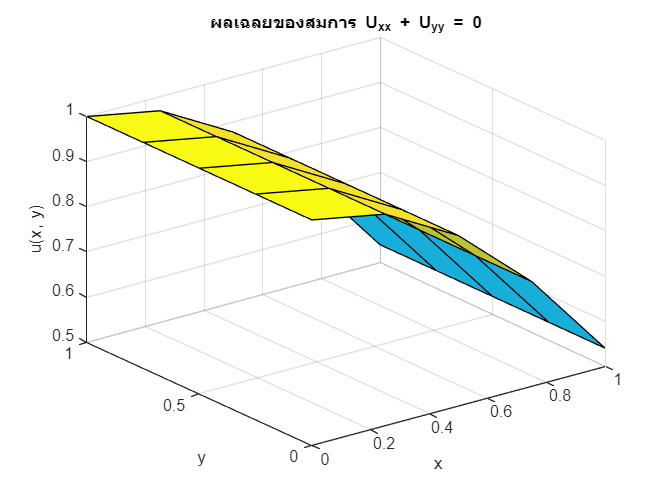

figure;
surf(x, y, u);
title('ผลเฉลยของสมการ U_{xx} + U_{yy} = 0');
xlabel('x');
ylabel('y');
zlabel('u(x, y)');

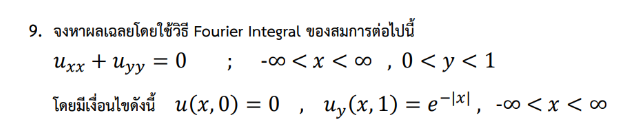

clearvars;clc;clf
syms x y k A B
u_x0 = 0;  % u(x,0) = 0
u_x1 = exp(-x);  % u(x,1) = e^(-x)

**Fourier transform of u(x,1)**

U_k = fourier(u_x1, x, k);
U_k_y = A*exp(-k*y) + B*exp(k*y);
eq1 = A + B == 0;  
eq2 = subs(U_k_y, y, 1) == U_k;  
sol = solve([eq1, eq2], [A, B]);
U_k_y_solution = subs(U_k_y, {A, B}, {sol.A, sol.B});

**Inverse Fourier transform to get u(x, y)**

u_xy = ifourier(U_k_y_solution, k, x);
disp(u_xy)

$$-\frac{\mathrm{fourier}\left(\frac{{\mathrm{e}}^{k\,y}\,\mathrm{fourier}\left({\mathrm{e}}^{-x},x,k\right)}{{\mathrm{e}}^{-k}-{\mathrm{e}}^{k}},k,-x\right)-\mathrm{fourier}\left(\frac{{\mathrm{e}}^{-k\,y}\,\mathrm{fourier}\left({\mathrm{e}}^{-x},x,k\right)}{{\mathrm{e}}^{-k}-{\mathrm{e}}^{k}},k,-x\right)}{2\,\pi }$$

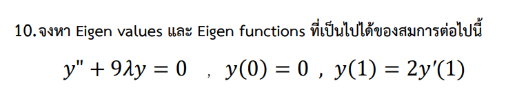

clearvars;clc;
syms k lambda

eq = sin(k) - 2*k*cos(k);
k_values = [];
for n = 1:5  
    k_guess = n*pi; 
    k_sol = vpasolve(eq, k, k_guess);  
    if ~isempty(k_sol) && all(~ismember(k_sol, k_values)) 
        k_values = [k_values, k_sol];  
    end
end

**eigenvalues lambda**

lambda_values = (k_values.^2) / 9; 

**Display eigenvalues**

disp('Eigenvalues (lambda):');

Eigenvalues (lambda):


disp(lambda_values);

$$\left(\begin{array}{ccccc} 4.6328018305212260263250569561245e-84 & 2.644700699300018413052723872237e-82 & 9.3351528835845978655885246438373e-81 & 1.6431918946931187067396093373664e-80 & 1.7427570974902958705251236478506e-80 \end{array}\right)$$

eigenfunctions = [];
for i = 1:length(lambda_values)
    eigenfunction = sin(sqrt(9*lambda_values(i))*sym('x'));
    eigenfunctions = [eigenfunctions; simplify(eigenfunction)];
end

**Display eigenfunctions**

disp('Eigenfunctions:');

Eigenfunctions:


disp(eigenfunctions);

$$\left(\begin{array}{c} \sin\left(6.4571833236087570628165459197999e-42\,x\right)\\ \sin\left(4.8787607333932831141280569171822e-41\,x\right)\\ \sin\left(2.8985578474865976148643161684435e-40\,x\right)\\ \sin\left(3.8456114016158819840774095700142e-40\,x\right)\\ \sin\left(3.9604057718133709985274814974773e-40\,x\right) \end{array}\right)$$